n = 1;
n_max = 1000;
r0 = [0; 0]; % initial position
R = r0;
grad = gradient(z);
lambda = 0.02; % initial lambda
delta = 0.99; % delta
tolerance = 0.1; % tolerance

while n < n_max && norm(grad_i) > tolerance
    r_i = R(:,n) + lambda * grad_i;
    R = [R, r_i];
    grad_i = vpa(subs(grad, [x; y], R(:, n+1)));
    lambda = delta * lambda;
    n = n + 1;
end

R

R =      0
     0


R(:,end)

ans =      0
     0


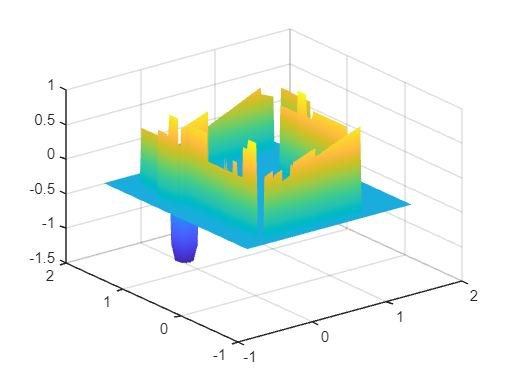


surf(x, y, z), shading interp

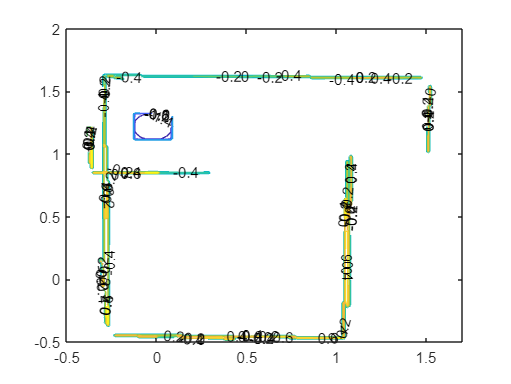

contour(x, y, z, 'ShowText','on')
hold on
plot(R(1,:), R(2,:))
hold off